clc; clear; close all;

x = linspace(-1,1)*5;
x = x(1:(end-1));
y = exp(-((x-randn(1))/(1+rand(1))).^2)+randn(size(x))*0.01;

[yMax, indMax] = max(y);

yt = yMax/2; % calculate threshold (half max)
ind = find(y > yt); % find when y exceeds threshold
xw = indMax; % calculate the width
xc = xw/2 % calculate the center

xc = 27.5000

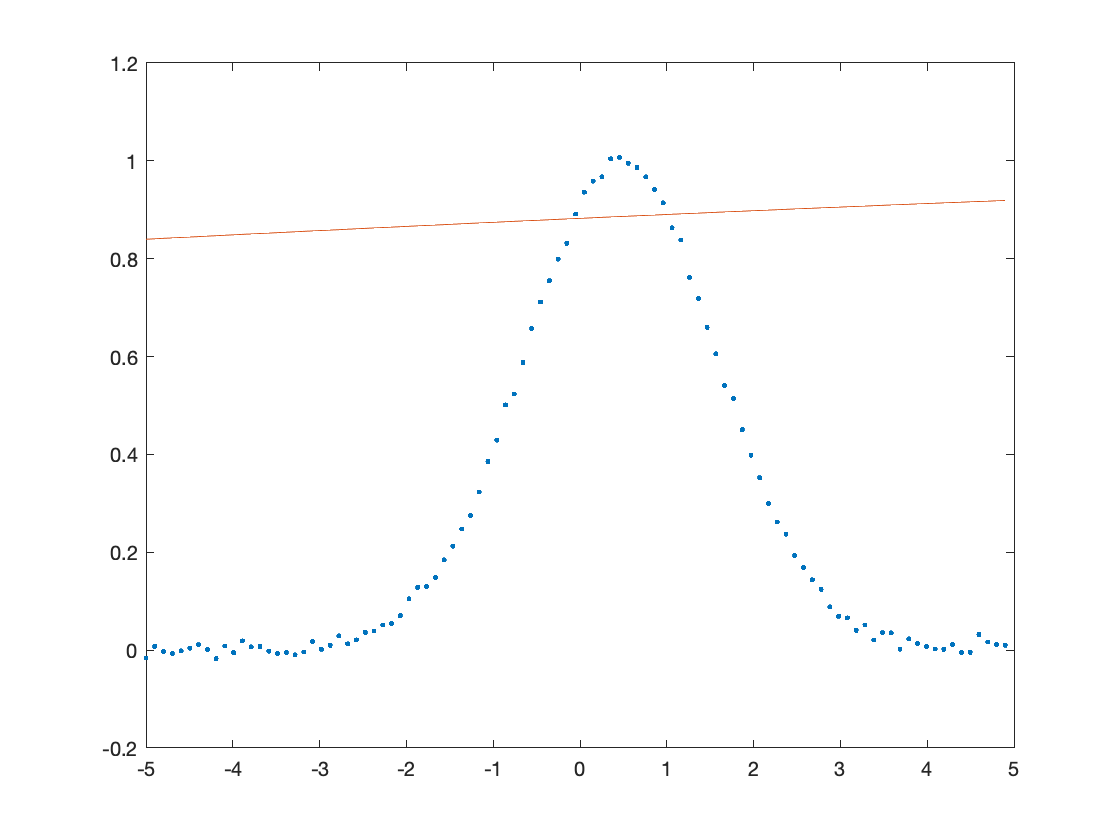


plot(x,y,'.',x,exp(-((x-xc)/(xw*sqrt(2))).^2),'-') % overlay for confirmation